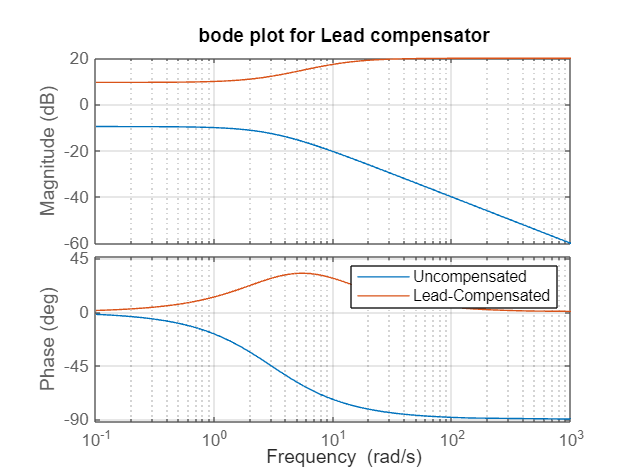

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

s = tf('s');
G1 = 1/(s + 3);
C_lead = 7*(s + 3)/(s + 12);
C_lag = (s + 1)/(s + 0.1);
C_total= G1*C_lead*C_lag;
C_L=feedback(C_total,1);
%%C_lead bode plots
figure;
bode(G1, C_lead);
grid on;
title('bode plot for Lead compensator')
legend('Uncompensated', 'Lead-Compensated')

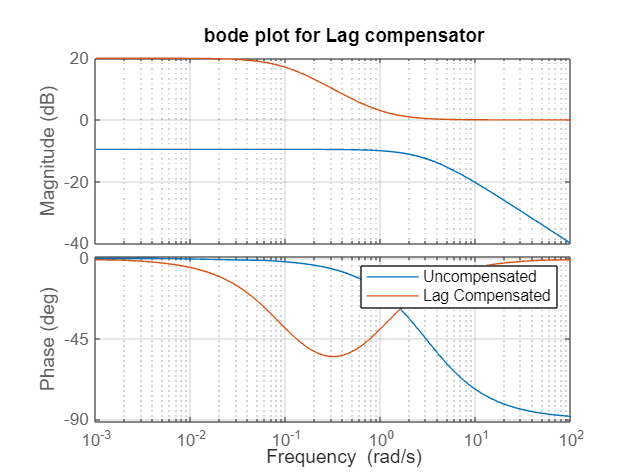

%%c-lag bode plot
figure;
bode(G1, C_lag);
grid on;
title('bode plot for Lag compensator')
legend('Uncompensated', 'Lag Compensated')

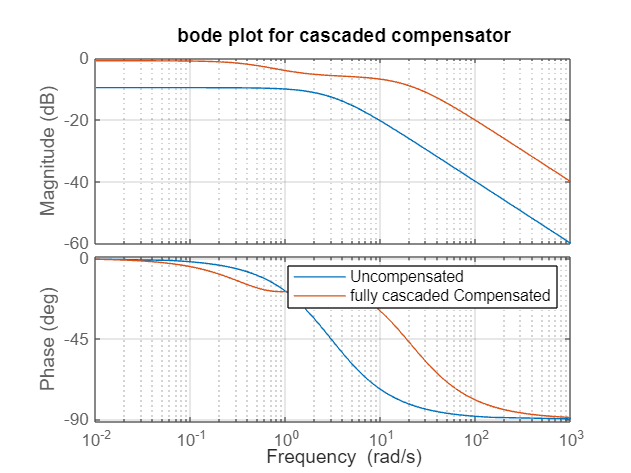

%%bode plot for compensated ssytem
figure;
bode(G1,C_L);
grid on;
title('bode plot for cascaded compensator')
legend('Uncompensated', 'fully Compensated')

%%plotting the step response

         RiseTime: 2.6611
    TransientTime: 5.5296
     SettlingTime: 5.5296
      SettlingMin: 0.8183
      SettlingMax: 0.9087
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9087
         PeakTime: 12.4411



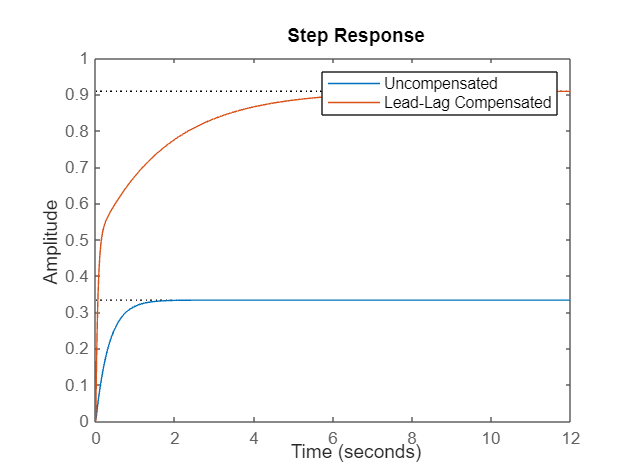

step(G1, C_L);
legend('Uncompensated', 'Lead-Lag Compensated')